# Lab 1 ESD2 - Oran Betz

Corke Toolbox:

+X: towards right side of camera

+Y: towards ground

+Z: Radially away from camera [optical axis]

## Hard Coded Parameters

loopmax = 2;
focalarrary = [6,10];
for c = 1:loopmax
b = 60;                   % baseline [mm]
f = focalarrary(c)/1e3;   % focal length [mm]
ps = .006/1e3;            % pixel size [mm]
xNumPix = 752;            % total number of pixels in x direction of the sensor [px]
yNumPix = 480;            % total number of pixels in y direction of the sensor [px]
cxLeft  = xNumPix/2;      % left camera x center [px]
cxRight = xNumPix/2;      % right camera x center [px]
cyLeft  = yNumPix/2;      % left camera y center [px]
cyRight = yNumPix/2;      % right camera y center [px]

## Camera Utilization and XYZ Position

camLeft = CentralCamera('focal', f, 'pixel',ps, 'resolution', [xNumPix,yNumPix], 'centre', [cxLeft,cyLeft]);
Tcam = SE3(-0.03,0,0); % Array allocation for XYZ position for left camera
camLeft.T = Tcam;
camRight = CentralCamera('focal', f, 'pixel',ps, 'resolution', [xNumPix,yNumPix], 'centre', [cxRight,cyRight]);
Tcam = SE3(0.03,0,0);  % Array allocation for XYZ position for right camera
camRight.T = Tcam;

## Plot Parameters

depth = 0:0.1:10; % Z Axis (10 was given)
numPoints = length(depth);
x = zeros(1,numPoints);
y = zeros(1,numPoints);

P = [x;y;depth];
leftPixel = camLeft.project(P);   % camLeft Class Return of Array
rightPixel = camRight.project(P); % camRight Class Return of Array

## Equations to find depth

xLeft = leftPixel(1,:);
xRight = rightPixel(1,:);

d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps)  % disparity [mm] (Actual - Expected) * Pixel Length
Z = (b * f)./d                                 % depth [mm] Array of Z
calculatedDepth = Z/1e3;                       % depth [m]  Array of Z

## Plot of Focal Length

d =        Inf    0.0036    0.0018    0.0012    0.0009    0.0007    0.0006    0.0005    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


Z = 1.0e+04 *

         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


d =        Inf    0.0060    0.0030    0.0020    0.0015    0.0012    0.0010    0.0009    0.0008    0.0007    0.0006    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


Z = 1.0e+04 *

         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


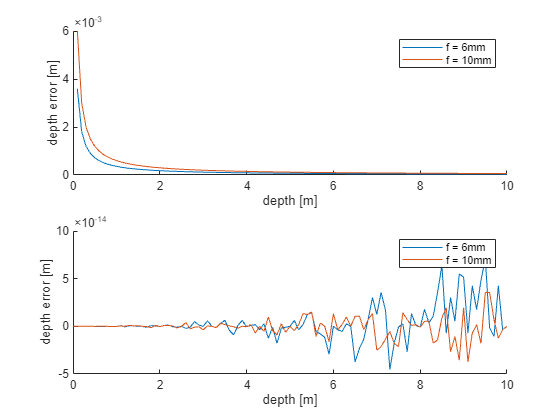

subplot(2,1,1) % (# of Y Points,# of X Plots ,# of Subplot)
hold on
plot(depth,d) % Z Position / Disparity (Per Pixel)
legend("f = 6mm", "f = 10mm")
xlabel("depth [m]")
ylabel("depth error [m]")
subplot(2,1,2)
hold on
plot(depth, calculatedDepth-depth); % Z Position / Disparity (Actual - Expected)
legend("f = 6mm", "f = 10mm")
xlabel("depth [m]")
ylabel("depth error [m]")

end